# by vs bx over one period 

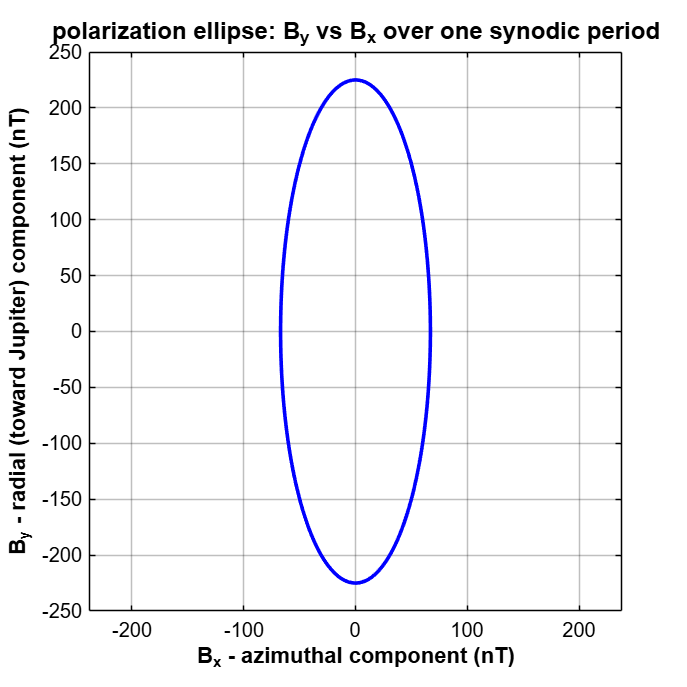

clear
% define constants
A = 0.95; % amplitude response factor (not used here, primary field only)
phi = 0.14; % phase lag in radians (not used here, primary field only)
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / synodic_period; % synodic freq. (rad/sec)

% elliptical primary field amplitudes from Zimmer's range (IS-system)
Bprim_x_amp = 67;  % azimuthal (orbital travel direction)
Bprim_y_amp = 225; % radial (pointing toward Jupiter)

% time array - one full synodic period
num_points = 500;
t = linspace(0, synodic_period, num_points);

% complex primary background field
Bprim_c_x = Bprim_x_amp * exp(-1i*omega*t);
Bprim_c_y = Bprim_y_amp * exp(-1i*(omega*t - pi/2));

% actual measurable Bx(t), By(t)
Bx = real(Bprim_c_x);
By = real(Bprim_c_y);

% plot the parametric curve
figure('Color', 'w');
set(gcf, 'Position', [100, 100, 700, 700]);

plot(Bx, By, 'b-', 'LineWidth', 1.8);
hold on;



axis equal; grid on; box on;
xlabel('B_x - azimuthal component (nT)', 'FontWeight', 'bold');
ylabel('B_y - radial (toward Jupiter) component (nT)', 'FontWeight', 'bold');
title('polarization ellipse: B_y vs B_x over one synodic period', ...
    'FontWeight', 'bold', 'Color', 'k', 'FontSize', 12);

set(gca, 'XColor', 'k', 'YColor', 'k', 'Color', 'w');


ylim([-250 250]);